# Lugar Geométrico de las Raíces

Estudiar como cambian las ubicaciones de las raíces de la funcion de transferencia, a medida que varía el controlador..

El comando para dibujar en matlab es rlocus

G=tf([1],[1 2])

G =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties


polo=pole(G)

polo = -2

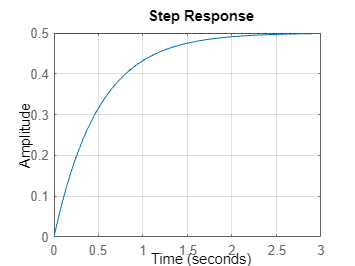

figure
step(G)
grid on

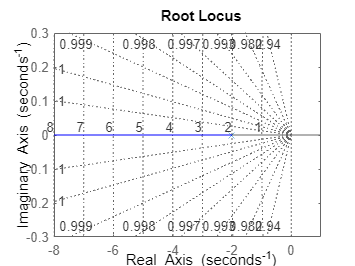

%%
figure
rlocus(G)
grid on

GLC=feedback(G,4)

GLC =
 
    1
  -----
  s + 6
 
Continuous-time transfer function.
Model Properties


polo=pole(GLC)

polo = -6

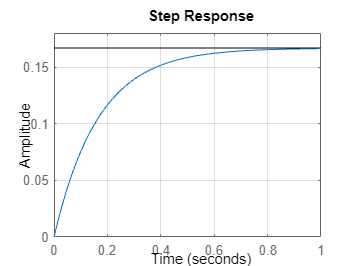

figure
step(GLC)
grid on

Para un sistema de segundo orden

G=tf([1],[1 1 2])

G =
 
       1
  -----------
  s^2 + s + 2
 
Continuous-time transfer function.
Model Properties


polo=pole(G)

polo =   -0.5000 + 1.3229i
  -0.5000 - 1.3229i


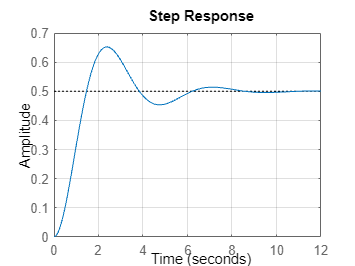

figure
step(G)
grid on

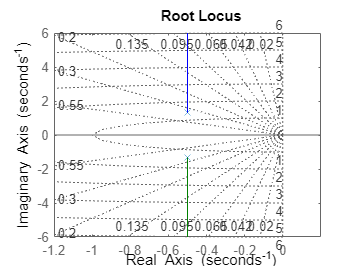

%%
figure
rlocus(G)
grid on

GLC=feedback(G,5.75)

GLC =
 
        1
  --------------
  s^2 + s + 7.75
 
Continuous-time transfer function.
Model Properties


poloS=pole(GLC)

poloS =   -0.5000 + 2.7386i
  -0.5000 - 2.7386i


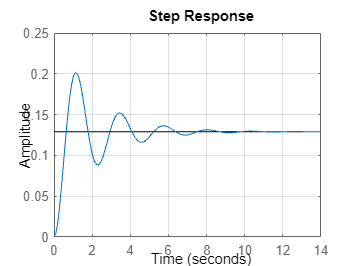

figure
step(GLC)
grid on

¿Que pasa si quiero diseñar en base a ciertas características?

R: Debo conocer la expresión simbólica de los polos en lazo abierto y en lazo cerrado...

Para un sistema de primer orden en forma canónica

syms K tau C  
s=sym('s')

$$s = s$$

G=K/(tau*s + 1)

$$G = \frac{K}{s\,\tau +1}$$

[N,D] = numden(G)

$$N = K$$

$$D = s\,\tau +1$$

eqn=D==0

$$eqn = s\,\tau +1=0$$

LA=solve(eqn,s)

$$LA = -\frac{1}{\tau }$$

GLC=G/(1+(G*C))

$$GLC = \frac{K}{\left(\frac{C\,K}{s\,\tau +1}+1\right)\,\left(s\,\tau +1\right)}$$

GLC=simplify (GLC)

$$GLC = \frac{K}{s\,\tau +C\,K+1}$$

[N,D] = numden(GLC)

$$N = K$$

$$D = s\,\tau +C\,K+1$$

tau=0.5

tau = 0.5000

K=0.5

K = 0.5000

eqn=D==0

$$eqn = s\,\tau +C\,K+1=0$$

eqn=eval(eqn)

$$eqn = \frac{C}{2}+\frac{s}{2}+1=0$$

LC=solve(eqn,s)

$$LC = -C-2$$

Para un sistema canónico de segundo orden

syms K omega_n zeta C  
s=sym('s')

$$s = s$$

G=K*omega_n^2/(s^2 + 2*zeta*omega_n*s + omega_n^2)

$$G = \frac{K\,{\omega_{n}}^{2}}{{\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}}$$

[N,D] = numden(G)

$$N = K\,{\omega_{n}}^{2}$$

$$D = {\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}$$

eqn=D==0

$$eqn = {\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}=0$$

LA=solve(eqn,s)

$$LA = \left(\begin{array}{c} \omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}-\omega_{n}\,\zeta \\ -\omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}-\omega_{n}\,\zeta \end{array}\right)$$

GLC=G/(1+(G*C))

$$GLC = \frac{K\,{\omega_{n}}^{2}}{\left(\frac{C\,K\,{\omega_{n}}^{2}}{{\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}}+1\right)\,\left({\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}\right)}$$

GLC=simplify (GLC)

$$GLC = \frac{K\,{\omega_{n}}^{2}}{{\omega_{n}}^{2}+s^{2}+2\,\omega_{n}\,s\,\zeta +C\,K\,{\omega_{n}}^{2}}$$

[N,D] = numden(GLC)

$$N = K\,{\omega_{n}}^{2}$$

$$D = {\omega_{n}}^{2}+s^{2}+2\,\omega_{n}\,s\,\zeta +C\,K\,{\omega_{n}}^{2}$$

eqn=D==0

$$eqn = {\omega_{n}}^{2}+s^{2}+2\,\omega_{n}\,s\,\zeta +C\,K\,{\omega_{n}}^{2}=0$$

K=0.5

K = 0.5000

omega_n=sqrt(2)

omega_n = 1.4142

zeta=(1/(sqrt(2)))/2

zeta = 0.3536

eqn=eval(eqn)

$$eqn = s^{2}+s+C+2=0$$

LC=solve(eqn,s)

$$LC = \left(\begin{array}{c} -\frac{\sqrt{-4\,C-7}}{2}-\frac{1}{2}\\ \frac{\sqrt{-4\,C-7}}{2}-\frac{1}{2} \end{array}\right)$$

C=25

C = 25

Lc=eval(LC)

Lc =   -0.5000 - 5.1720i
  -0.5000 + 5.1720i
